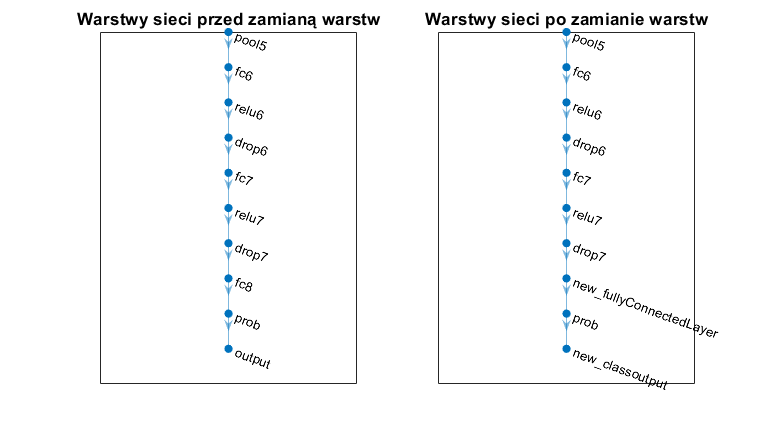

%Wykorzystanie transferu uczenia do ponownego nauczenia konwolucyjnej sieci
%neuronowej klasyfikowania obrazów
clc
clear
%Obiektem wejściowym sieci neuronowej jest obraz. Sieć zwraca nazwę
%kategori, do której należy obraz, wraz z prawdopodobieństwem
%przynależności do danej kategori.
%Wykonanie zadania klasyfykacji nowego zestawu obrazów polega na
%wykorzystaniu istniejącej już, wstępnie przeszkolonej sieci i dostrojenie
%jej a pomocą transferu uczenia.

%Zadanie to realizuje się w następujących punktach:
%1. Wczytanie wstępnie wytrenowanej sieci (np. Alexnet).
%2. Zastąpienie końcowych warstw sieci nowymi warstwami.
%3. Trenowanie sieci (na podstawie nowej bazy danych zdjęć i opcji
%trenowania)
%4. Predykcja i ocena dokładności sieci (wykorzystanie obrazów testowych).
%5. Wyświetlenie wyników.


%Wczytanie bazy danych zdjęć i podział zbioru zdjęć na zbiór danych uczącyc
%się i zbór danych walidacyjnych (sprawdzającego poprawność danych).

%Ścieżka do bazy danych zdjęć
folderPath = 'E:\machine_vision\Radar-images';
%Utworzenie bazy danych w programie Matlab
imds = imageDatastore(folderPath, ...
    'IncludeSubfolders',true, ... 
    'LabelSource','foldernames');
%Dostosowanie nazw radarów
changeName = imds.Labels == "AN_MPQ-53";
imds.Labels(changeName) = "AN/MPQ-53"; imds.Labels = removecats(imds.Labels, 'AN_MPQ-53');
changeName = imds.Labels == "AN_TPS-70";
imds.Labels(changeName) = "AN/TPS-70"; imds.Labels = removecats(imds.Labels, 'AN_TPS-70');
%Podział zbioru danych na dwa zbiory (uczący się i walidacyjny)
%w proporcji 7:3.
[imdsTrain,imdsValidation] = splitEachLabel(imds, 0.7,'randomized');

%Wczytanie wstępnie wytrenowanej sieci
net = alexnet;

%Wizualizacja architektury sieci. Zawiera informacje o warstwach sieci
%(rozmiary danych wejściowych, parametrów możliwych do nauczenia, całkiwitą
%liczbę parametrów możliwych do nauczenia, rozmiary parametrów stanu
%powtarzających się warstw).
% analyzeNetwork(net);

%Dane wejściowe obrazu do sieci (wysokość, szerokość, wymiar)
%Dla sieci Alexnet jest to 227x227x3.
inputSize = net.Layers(1).InputSize;

%Zamiana dwóch warstw sieci (learnable layer and classification layer) na dwie 
% nowe warstwy dostosowane do nowego zestawu danych.

%Sprawdzenie, czy dana sieć jest obiektem typu 'SeriesNetwork' i konwersja
%listy warstw na obiekt typu 'layerGraph' (graf warstwowy).
%Graf warstwowy określa architekturę sieci głębokiego uczenia się z bardziej 
% złożoną strukturą grafu, w której warstwy mogą mieć wejścia z wielu warstw 
% i wyjścia do wielu warstw.
if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end

%Rysunek warstw
figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
subplot(1,2,1);
plot(lgraph);
ylim([0,10]);
title('Warstwy sieci przed zamianą warstw');
grid on;
% ax = gca;
% grid on;
% ax.XGrid = 'off';
% ax.YGrid = 'on';

%Wywołanie funkcji 'findLayersToReplace' do znalezienia warstw do zamiany
[learnableLayer, classLayer] = findLayersToReplace(lgraph);

%Liczba rodzajów radarów do rozpoznania
numClasses = numel(categories(imdsTrain.Labels));

%Utworzenie nowych warstw (fullly-connected layer - warstwy w pełni
%połączonej; convolution layer - warstwa splotowa)
%Określenie wag i współczynników odchyleń (biases)
if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fullyConnectedLayer', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_convolution2dLayer', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

%Wywołanie funkcji zamieniającej warstwe w sieci
lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

%Zamiana warstwy klasyfikacji określająca klasy wyjściowe (nazwy radarów)
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

%Rysunek zamienionych warstw
subplot(1,2,2);
plot(lgraph);
ylim([0,10]);
title('Warstwy sieci po zamianie warstw');

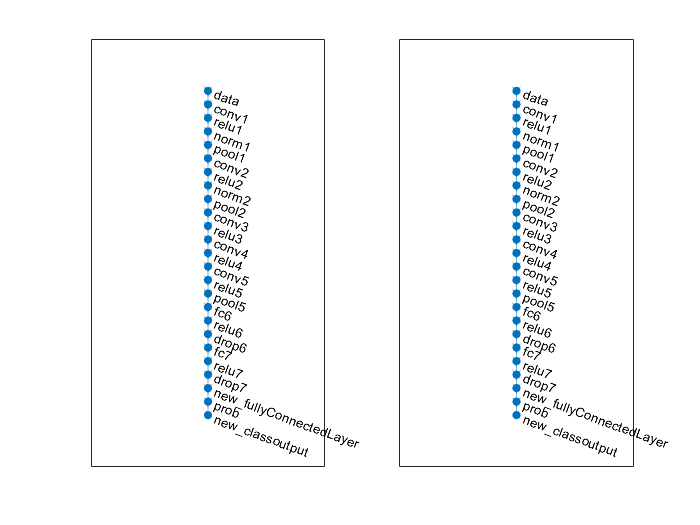


%Zamrożenie wag wcześniejszych warstw w sieci poprzez ustawienie
%wspołczynniki prędkości uczenia na zero. Dzięki temu, w trakcie uczenia
%się sieci, trenowana sieć nie będzie aktualizowała parametrów warstw
%zamrożonych. Ponieważ gradienty zamrożonych warstw nie muszą być obliczane, 
%zamrożenie wag początkowych warstw może znacznie przyśpieszyć proces
%uczenia się sieci. Jeśli baza danych zdjęć jest mała to zamrożenie warstw
%zapobiega również przetrenowaniu sieci (algorytm uczy się poszczególnych
%przypadków, a nie ogólnych zasad).

layers = lgraph.Layers;
connections = lgraph.Connections;

numLayersToFreeze = 10;
%Wywołanei funkcji 'freezeWeights' w celu stawienia współczynników uczenia
%się na zera dla 'numLayersToFreeze' pierwszych warstw
layers(1:numLayersToFreeze) = freezeWeights(layers(1:numLayersToFreeze));
%Funkcja 'createLgraphUsingConnections' ponownie łączny wszystkie warstwy 
% w oryginalnej kolejności
lgraph = createLgraphUsingConnections(layers, connections);


%TRENOWANIE SIECI
%Różne sieci wymagają innego rozmiaru wejściowego obrazu (np. siec Alexnet
%wymaga rozmiaru 227x227x3). Obrazu w bazie danych posiadają inne rozmiary.
